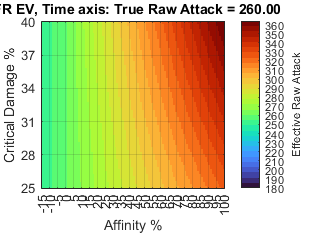

%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Script Init %%%%%
%%%%%%%%%%%%%%%%%%%%%%%

clear;

% 90 is the lowest true attack I could find; ~300 with armor skills might be tops
raw_bounds = [180, 260];

% -15% Affinity on the Gravios SnS to the 100% Affinity I get with Black
% Eclipse + Maximum Might
aff_bounds = [-15, 100];

% AFAIK only Critical Boost can modify Critical Damage %, which it does
% from 28% to 40%
crit_bounds = [25, 40];   

nFrames = 100;

vec_raw = linspace(raw_bounds(1), raw_bounds(2), 100);
vec_aff = linspace(aff_bounds(1), aff_bounds(2), 100);
vec_crit = linspace(crit_bounds(1), crit_bounds(2), 100);

efr_col_palette = turbo(32);

efrlb = raw_bounds(1);
efrub = raw_bounds(2)*1.4;
vec_colorbar_domain = efrlb:10:efrub;
vec_colorbar_bounds = [efrlb efrub];


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% EFR t -> True Raw Attack %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[AFF, CRIT] = meshgrid(vec_aff, vec_crit);

for idx = 1:nFrames
    hfnEFR_ac = arrayfun(@(A, C) EVd([vec_raw(idx); A; C]), AFF, CRIT);

    imagesc(vec_aff, vec_crit, hfnEFR_ac);
    grid(gca, 'on');
    set(gca, 'YDir', 'normal');
    clim(gca, vec_colorbar_bounds);
    colormap(efr_col_palette);

    hColBar = colorbar;
    hColBar.Ticks = vec_colorbar_domain;
    ylabel(hColBar, 'Effective Raw Attack');


    xlabel('Affinity %');
    ylabel('Critical Damage %');
    xticks(aff_bounds(1):5:aff_bounds(2));    
    yticks([25 28 31 34 37 40]);

    title(sprintf('EFR EV, Time axis: True Raw Attack = %.2f', vec_raw(idx)));

    drawnow;
    pause(0.01);
end

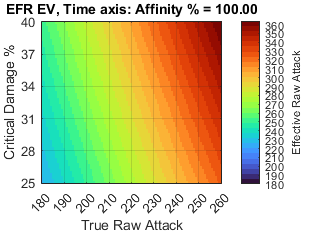



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% EFR t -> Affinity Pct %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[RAW, CRIT] = meshgrid(vec_raw, vec_crit);

for idx = 1:nFrames
    hfnEFR_rc = arrayfun(@(R, C) EVd([R; vec_aff(idx); C]), RAW, CRIT);

    imagesc(vec_raw, vec_crit, hfnEFR_rc);
    grid(gca, 'on');    
    set(gca, 'YDir', 'normal');
    clim(gca, vec_colorbar_bounds);
    %clim(gca, 'auto');
    colormap(efr_col_palette);

    hColBar = colorbar;
    hColBar.Ticks = vec_colorbar_domain;
    ylabel(hColBar, 'Effective Raw Attack');

    xlabel('True Raw Attack');
    ylabel('Critical Damage %');
    xticks(raw_bounds(1):10:raw_bounds(2));
    yticks([25 28 31 34 37 40]);

    title(sprintf('EFR EV, Time axis: Affinity %% = %.2f', vec_aff(idx)));

    drawnow;
    pause(0.01);
end

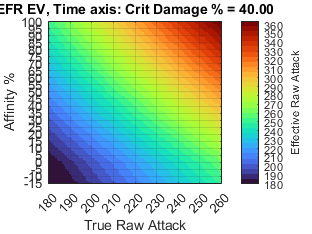



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% EFR t -> Crit Dmg Pct %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[RAW, AFF] = meshgrid(vec_raw, vec_aff);

for idx = 1:nFrames
    hfnEFR_ra = arrayfun(@(R, A) EVd([R; A; vec_crit(idx)]), RAW, AFF);

    imagesc(vec_raw, vec_aff, hfnEFR_ra);
    grid(gca, 'on');    
    set(gca, 'YDir', 'normal');
    clim(gca, vec_colorbar_bounds);

    colormap(efr_col_palette);
    hColBar = colorbar;
    hColBar.Ticks = vec_colorbar_domain;
    ylabel(hColBar, 'Effective Raw Attack');


    xlabel('True Raw Attack');
    ylabel('Affinity %');
    xticks(raw_bounds(1):10:raw_bounds(2));
    yticks(-15:5:100);

    title(sprintf('EFR EV, Time axis: Crit Damage %% = %.2f', vec_crit(idx)));

    drawnow;
    pause(0.01); 
end